## **3.1) Forming the Images**

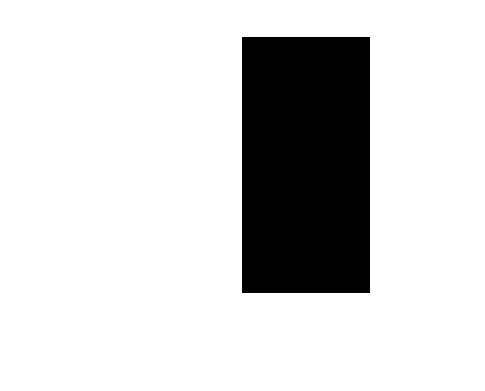

clear
M1=ones(256);
M1(:,129:256)=0;
imwrite(M1,'image1.jpg');
M2=ones(256);
M2(65:192,65:192)=0;
imwrite(M2,'image2.jpg');
M3=ones(256);
for i=0:63
    M3(65+i,128-i:128+i)=0;
end
for i=0:63
    M3(192-i,128-i:128+i)=0;
end
imwrite(M3,'image3.jpg');
imshow(M1);

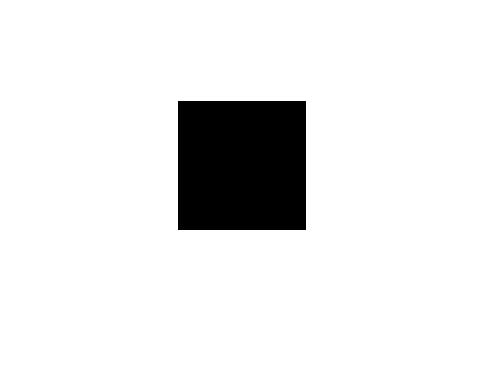

imshow(M2);

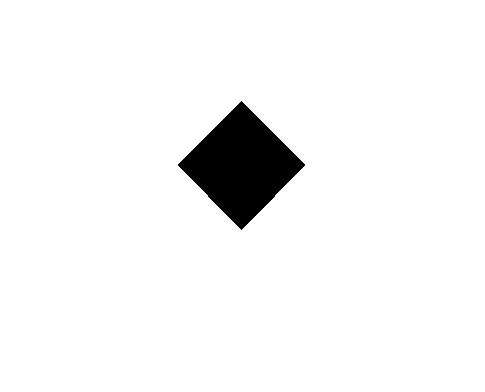

imshow(M3);

## 3.2) 2-D Fourier Transform

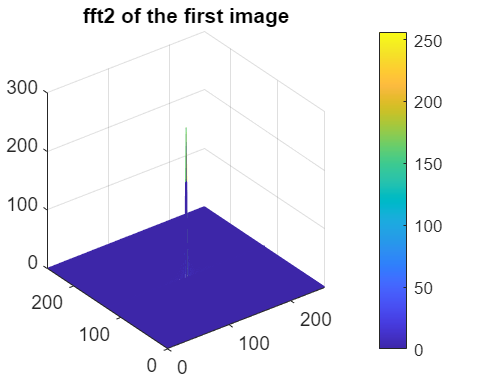

FT_M1=fftshift(fft2(M1));
FT_M1=256*FT_M1/max(max(FT_M1));
mesh(abs(FT_M1));
title('fft2 of the first image')
colorbar

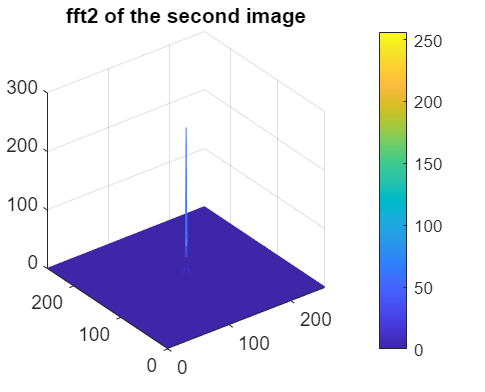

FT_M2=fftshift(fft2(M2));
FT_M2=256*FT_M2/max(max(FT_M2));
mesh(abs(FT_M2));
colorbar
title('fft2 of the second image')

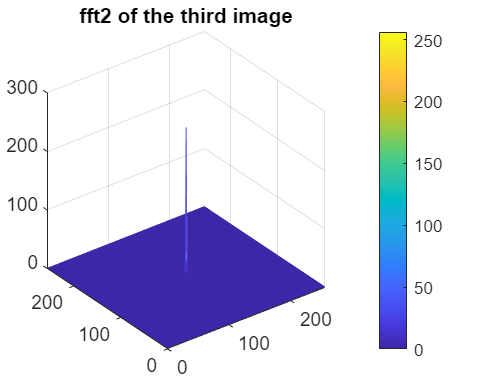

FT_M3=fftshift(fft2(M3));
FT_M3=256*FT_M3/max(max(FT_M3));
mesh(abs(FT_M3));
colorbar
title('fft2 of the third image')

## 3.3) 5% Compression

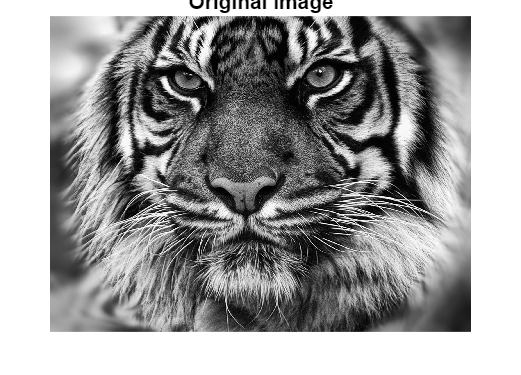

image=imread("tiger.jpg");
imshow(image)
title('Original Image')

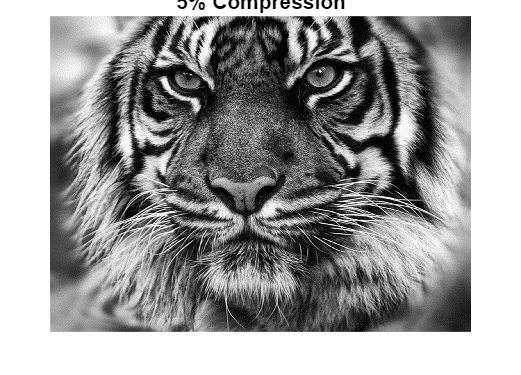

im_fft2=fft2(image);
threshold=3.3e-4*max(max(abs(im_fft2)));
index=abs(im_fft2)>threshold;
filtered_image=im_fft2.*index;
com_image=uint8(ifft2(filtered_image)); 
imshow(com_image);
title('5% Compression')

imwrite(com_image,'5%Compressed.jpg');

##  50% Compression

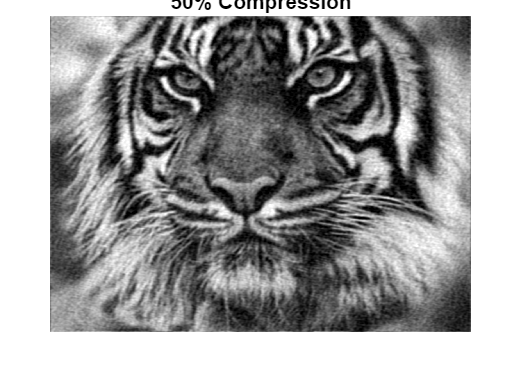

threshold=1.275e-3*max(max(abs(im_fft2)));
index=abs(im_fft2)>threshold;
filtered_image=im_fft2.*index;
com_image=uint8(ifft2(filtered_image)); 
imshow(com_image);
title('50% Compression')

imwrite(com_image,'50%Compressed.jpg');